syms omega s t 
FS=omega/(s*(s^2+omega^2))

$$FS = \frac{\omega }{s\,\left(\omega^{2}+s^{2}\right)}$$

a = partfrac(FS,s)

$$a = \frac{1}{\omega \,s}-\frac{s}{\omega \,\left(\omega^{2}+s^{2}\right)}$$

ilaplace(a)

$$ans = \frac{1}{\omega }-\frac{\cos\left(\omega \,t\right)}{\omega }$$

ft=1/(2*pi)*heaviside(t)+1/(2*pi)*cos((2*pi)*t)*heaviside(t)

$$ft = \frac{5734161139222659\,\mathrm{heaviside}\left(t\right)}{36028797018963968}+\frac{5734161139222659\,\cos\left(2\,\pi \,t\right)\,\mathrm{heaviside}\left(t\right)}{36028797018963968}$$

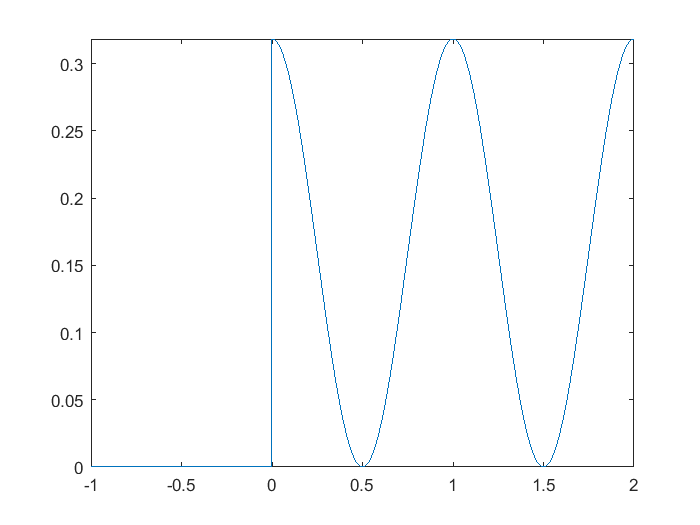


fplot(ft,[-1 2])

fin=sin((2*pi*t))*heaviside(t)

$$fin = \sin\left(2\,\pi \,t\right)\,\mathrm{heaviside}\left(t\right)$$

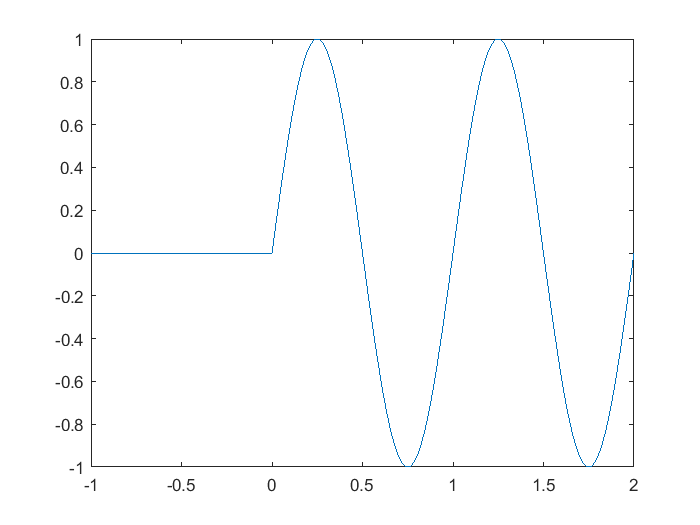

fplot(fin,[-1 2])

ilaplace(1/(s^2+omega^2),s)

$$ans = \frac{\sin\left(\omega \,s\right)}{\omega }$$